## 画像の読み出し

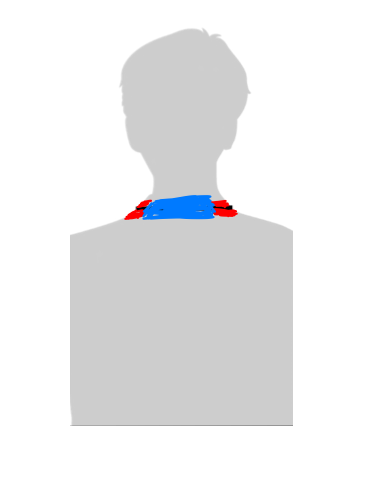

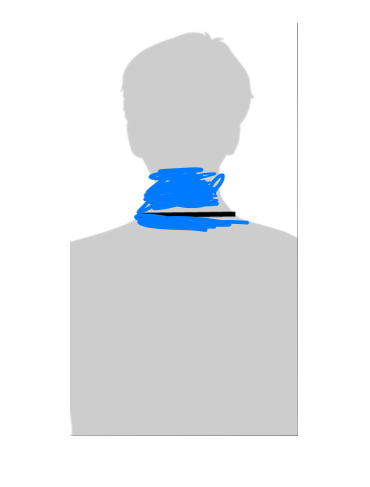

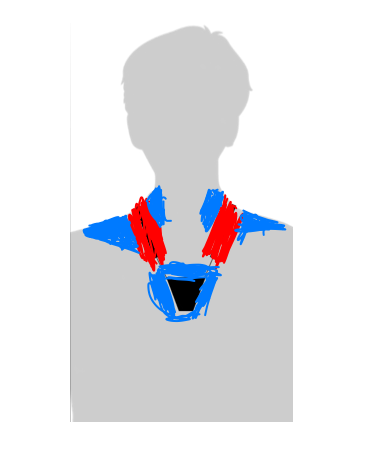

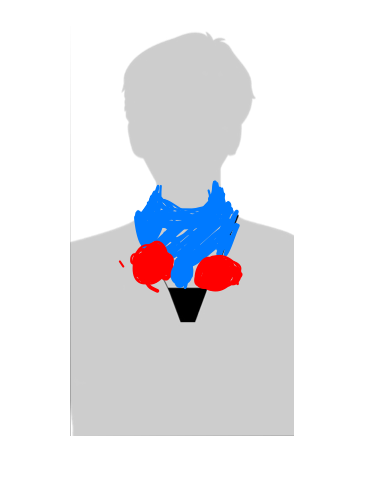

list = dir('*.png');
numFiles = length(list);
Graph = cell(numFiles,numFiles);

for i = 1:numFiles
RGB = imread(list(i).name);
figure, imshow(RGB);
Graph{i,5} = list(i).name;
Graph{i,6} = RGB;

## 強い部分だけ取り出し


% Convert RGB image to chosen color space
I_Red = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.792;
channel1Max = 0.000;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.667;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.882;
channel3Max = 1.000;

% Create mask based on chosen histogram thresholds
sliderBW_Red = ( (I_Red(:,:,1) >= channel1Min) | (I_Red(:,:,1) <= channel1Max) ) & ...
    (I_Red(:,:,2) >= channel2Min ) & (I_Red(:,:,2) <= channel2Max) & ...
    (I_Red(:,:,3) >= channel3Min ) & (I_Red(:,:,3) <= channel3Max);
BW_Red = sliderBW_Red;

BW_Red_out = BW_Red;

% Fill holes in regions.
BW_Red_out = imfill(BW_Red_out, 'holes');

% Filter image based on image properties.
BW_Red_out = bwpropfilt(BW_Red_out, 'Area', [20, 1439]);

% Red_Stats = regionprops('table',BW_Red_out,'Centroid','Area','Extrema',...
%     'MajorAxisLength','MinorAxisLength','Perimeter','PixelList')
Red_Stats = regionprops('table',BW_Red_out,'Centroid','Area','Perimeter','PixelList');

%
Graph{i,1} = BW_Red_out;
Graph{i,2} = Red_Stats;

## **弱い部分だけ取り出し**

%%弱い部分だけ取り出し
% Convert RGB image to chosen color space
I_Blue = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.533;
channel1Max = 0.777;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.000;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = 1.000;

% Create mask based on chosen histogram thresholds
sliderBW_Blue = (I_Blue(:,:,1) >= channel1Min ) & (I_Blue(:,:,1) <= channel1Max) & ...
    (I_Blue(:,:,2) >= channel2Min ) & (I_Blue(:,:,2) <= channel2Max) & ...
    (I_Blue(:,:,3) >= channel3Min ) & (I_Blue(:,:,3) <= channel3Max);
BW_Blue = sliderBW_Blue;
BW_Blue_out = BW_Blue;

% Fill holes in regions.
BW_Blue_out = imfill(BW_Blue_out, 'holes');

% Filter image based on image properties.
BW_Blue_out = bwpropfilt(BW_Blue_out, 'Area', [10, 5995]);

% %Blue_Stats = regionprops('table',BW_Blue_out,'Centroid','Area','Extrema',...
%     'MajorAxisLength','MinorAxisLength','Perimeter','PixelList')
Blue_Stats = regionprops('table',BW_Blue_out,'Centroid','Area','Perimeter','PixelList');

Graph{i,3} = BW_Blue_out;
Graph{i,4} = Blue_Stats;

end

## グラフ化

A = 0;

for i = 1:numFiles
A  = A +  sum(Graph{i,2}{:,'Area'})

end
% Graph.BlueArea = sum(Blue_Stats{:,'Area'})
%  Z = imlincomb(0.5,Graph{1, 6},0.5,J)





A = 401

A = 401

A = 1733

A = 4503